data = readtable('Data 208.xlsx');
data.Properties.VariableNames = {'Strain','Strain Rate','T1','T2','T3','T4','T5','T6'}

data = 31×8 table
    Strain    Strain Rate     T1      T2      T3      T4      T5      T6 
    ______    ___________    ____    ____    ____    ____    ____    ____

     NaN           NaN        300     350     400     450     500     550
     0.1         0.001       16.1    8.87     5.3     4.1     2.2    1.52
     0.1          0.01       18.5    14.1     9.5     7.7     5.3    3.42
     0.1           0.1       23.5      19    13.6    10.9     8.1     6.2
     0.1             1       30.4      23    17.8    15.7    11.5     9.7
     0.1            10       33.2      31    25.9    20.3    15.8    13.7
     0.1           100       42.8    36.1    31.5    26.4      22    19.3
     0.2         0.001         18    10.1  

data(1,:)=[];

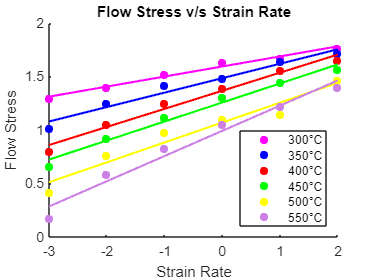

datan= table2array(data);
% 0.1 strain
strain_1 = datan(13:18,2:end);
sr1 = strain_1(:,1);
strainlog = log10(sr1);
stress1 = strain_1(:,2:end);y = zeros(6,6);
stresslog = log10(stress1);
C = {'m','b','r','g','y',[.8 .5 .9]};
hold on
for r = 1:length(stress1)
Scatter(r) =scatter(strainlog,stresslog(:,r),'filled','MarkerFaceColor',C{r});
c= polyfit(log10(sr1),log10(stress1(:,r)),1);
y(:,r) = polyval(c,log10(sr1));
plot(log10(sr1),y(:,r),'LineWidth',1.5,'Color',C{r})
end
ylabel('Flow Stress');xlabel('Strain Rate');
title('Flow Stress v/s Strain Rate')
legend(Scatter,'300°C','350°C','400°C','450°C','500°C','550°C','Location','southeast')
hold on

t1stress  = stress1(:,1);

%slope or strain rate sensitivity
m= zeros(length(stress1),length(stress1));
for k = 1:length(stress1)
for p = 1:length(stress1)
c1= polyfit(log10(sr1),log10(stress1(:,k)),3);
deriv = polyder(c1);
m(p,k) = polyval(deriv,strainlog(p));
end
end

e= (2*m./(m+1))*100;
T= 300:50:550;
%instability zone 
e1= e/200;
slope= zeros(length(stress1),length(stress1));
for k = 1:length(stress1)
for p = 1:length(stress1)
c2= polyfit(log10(sr1),log10(e1(:,k)),3);
deriv = polyder(c2);
slope(p,k) = polyval(deriv,strainlog(p));
end
end
iz = slope +m; %instability zone matrix

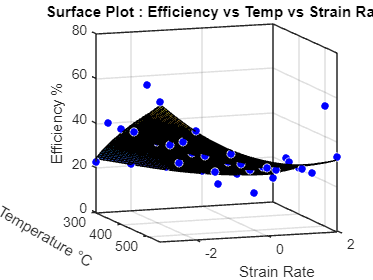

%%surface
%% Fit: 'untitled fit 1'.
[xData, yData, zData] = prepareSurfaceData( T, strainlog, e );
% Set up fittype and options.
ft = fittype( 'loess' );
opts = fitoptions( 'Method', 'LowessFit' );
opts.Normalize = 'on';
opts.Robust = 'Bisquare';
opts.Span = 0.75;
% Fit model to data.
[fitresult, ~] = fit( [xData, yData], zData, ft, opts );
% Make contour plot.
figure( 'Name', 'untitled fit 1' );
plot( fitresult, [xData, yData], zData, 'Style', 'Surface' );
% Label axes
xlabel( 'Temperature °C ', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );
zlabel('Efficiency %')
view([70 10]);
set(get(gca,'xlabel'), 'Rotation',-30);
title('Surface Plot : Efficiency vs Temp vs Strain Rate');

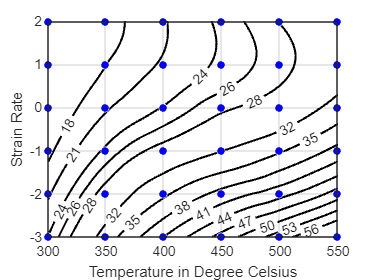

%% Fit: 'untitled fit 1'.
[xData, yData, zData] = prepareSurfaceData( T, strainlog, e );
% Set up fittype and options.
ft = fittype( 'loess' );
opts = fitoptions( 'Method', 'LowessFit' );
opts.Normalize = 'on';
opts.Robust = 'Bisquare';
opts.Span = 0.75;
% Fit model to data.
[fitresult, ~] = fit( [xData, yData], zData, ft, opts );
% Make contour plot.
figure( 'Name', 'untitled fit 1' );
h=plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );
% Label axes
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );
grid on
set(h(1),'ShowText','on','LabelSpacing',144)
set(h(1),'LineWidth',1.5,'Fill','off');
set(h(1),'LevelList',[18,21,24,26,28,32,35,38,41,44,47,50,53,56])
saveas(gcf,'pd0_1.jpg')

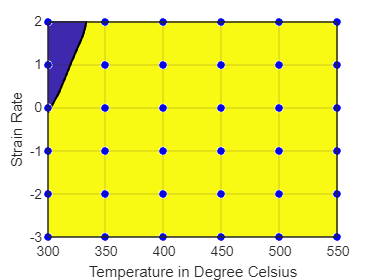

%% Fit: Instability map .
[xData, yData, zData] = prepareSurfaceData( T, strainlog, iz );
% Set up fittype and options.
ft = fittype( 'loess' );
opts = fitoptions( 'Method', 'LowessFit' );
opts.Normalize = 'on';
opts.Robust = 'Bisquare';
opts.Span = 0.75;
% Fit model to data.
[fitresult, gof] = fit( [xData, yData], zData, ft, opts );
% Make contour plot.
figure( 'Name', 'untitled fit 1' );
w=plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );
% Label axes
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );
grid on
set(w(1),'LineWidth',1.5,'LevelStep',2);
fig = gcf;
saveas(gcf,'is0_1.jpg')

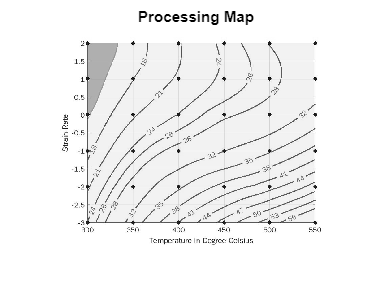

%%https://in.mathworks.com/help/curvefit/fit-smooth-surfaces-to-investigate-fuel-efficiency.% BASIC IMAGE PROCESSING : SUPERIMPOSE
fig1 = imread('pd0_1.jpg');
fig2 = imread('is0_1.jpg');
fusionimage=imfuse(fig1,fig2,'falsecolor','Scaling','joint');
op=rgb2gray(fusionimage);
op= imresize(op,[1968 2622]);
imshow(op )
title('Processing Map')